Laden Sie ein Farbbild Ihrer Wahl ein und  stellen es dar. Konvertieren Sie das Bild in ein Grauwertbild und stellen es dar. Wählen Sie aus dem Bild einen Auschnitt Ihrer Wahl und stellen Sie diesen dar. 

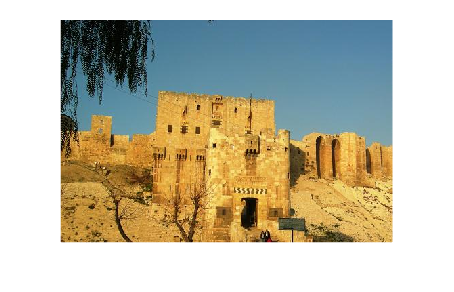

%Ihre Lösung
bild = imread('aleppo_citadel_01.jpg');
imshow(bild)

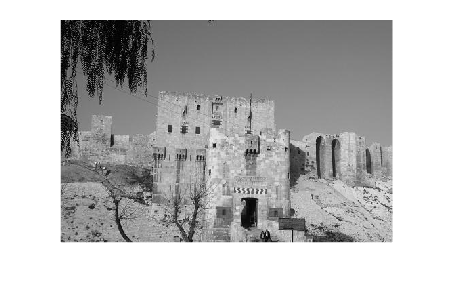

bildGray = rgb2gray(bild);
imshow(bildGray)

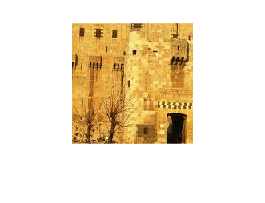

bild = bild(150:300, 150:300,:);
imshow(bild)

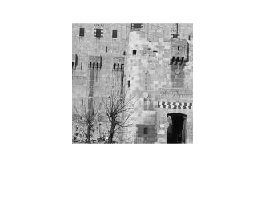

bildGray = bildGray(150:300, 150:300,:);
imshow(bildGray)

Laden Sie ein Bild Ihrer Wahl und stellen es dar. Rotieren Sie es um 90 ° und stellen es dar. 

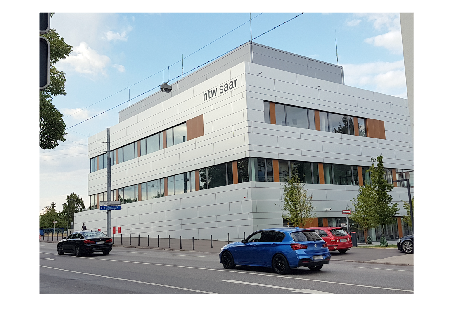

%Ihre Lösung
bild = imread('htw_saar.png');
imshow(bild)

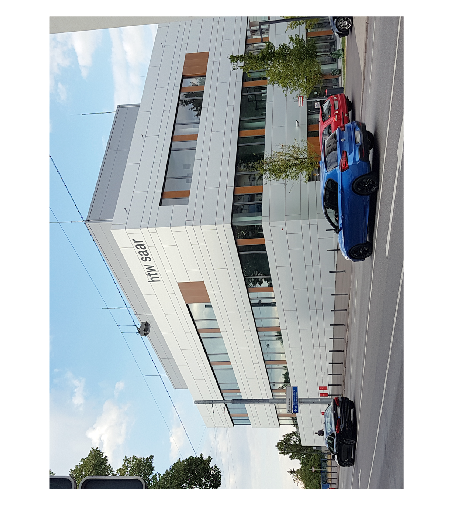

bild = imrotate(bild, 90);
imshow(bild)

Laden und filtern Sie das verrauschte Bild "verrauscht.png" um die Qualität zu verbessern mit einem Median Filter.  Beurteilen Sie das Ergebnis.  

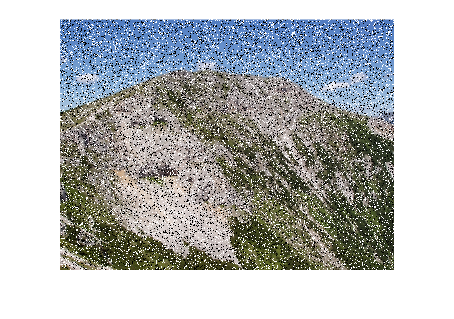

%Ihre Lösung
bild = imread('verrauscht.png');
imshow(bild)

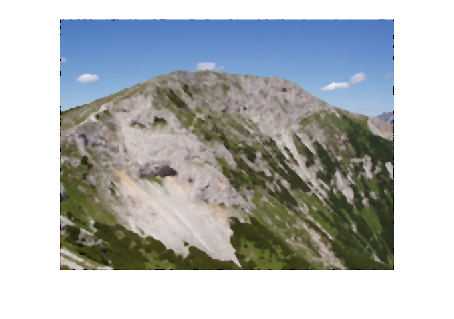

bildR = medfilt2(bild(:,:,1), [5 5]);
bildG = medfilt2(bild(:,:,2), [5 5]);
bildB = medfilt2(bild(:,:,3), [5 5]);

bild(:,:,1) = bildR;
bild(:,:,2) = bildG;
bild(:,:,3) = bildB;
imshow(bild)

Bei mikroskopischen Fluoreszensaufnahmen werden zur Erhöhung der Sensitivität monochrome Kameras eingesetzt, die mit Farbfiltern mehrere Aufnahmen machen. Gegeben sind die drei monochromen Aufnahmen der Fluoreszenz von RFP=Rot fluoreszierendes Protein,  GFP = Grün fluoreszierendes Protein und DAPI, ein blaufluoreszierender DNA Farbstoff) (Zellen_r,Zellen_g,Zellen_b) . Kombinieren Sie diese Einzelbilder zu einem Farbbild und stellen dieses dar. 

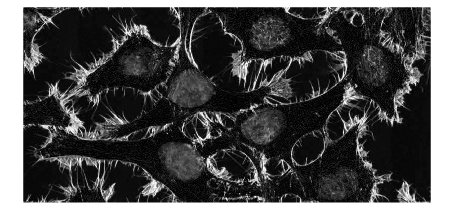

%Ihre Lösung
zellen_r = imread('Zellen_r.jpg');
zellen_g = imread('Zellen_g.jpg');
zellen_b = imread('Zellen_b.jpg');
imshow(zellen_r)

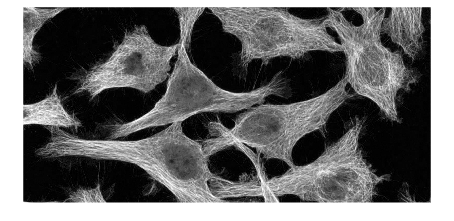

imshow(zellen_g)

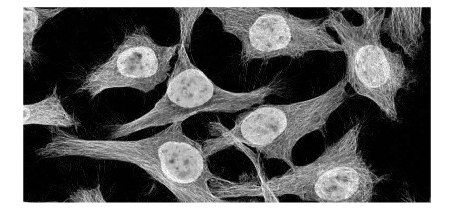

imshow(zellen_b)

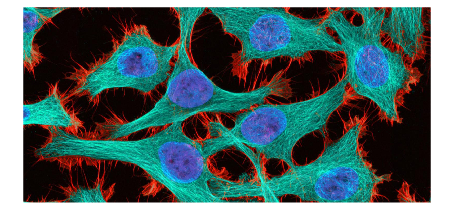

komniniertesbild(:,:,1) = zellen_r;
komniniertesbild(:,:,2) = zellen_g;
komniniertesbild(:,:,3) = zellen_b;
imshow(komniniertesbild)

Ultraschall-Dopplersignale werden zur Auswertung von Blutflussdaten genutzt. Üblicherweise wird das Dopplersignal als Farbinformation innerhalb eines Grauwertbildes angezeigt. (Daher der Name Farbdoppler). Laden Sie die Bilder US_1_B1.bmp und US_1_D1.bmp und stellen sie die Farbinformation und das Grauwertbild überlagert dar. Welche Überlagerung eignet sich am Besten? 

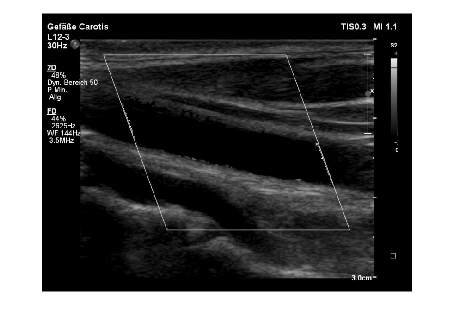

%Ihre Lösung
us_1_b1 = imread('US_1_b1.bmp');
us_1_d1 = imread('us_1_D.bmp');
imshow(us_1_b1)

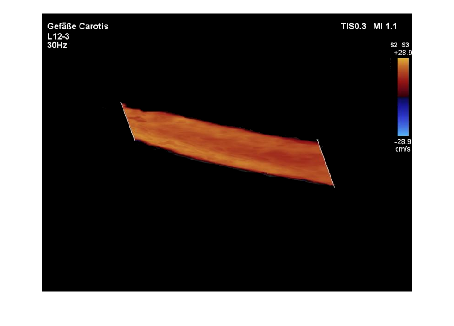

imshow(us_1_d1)

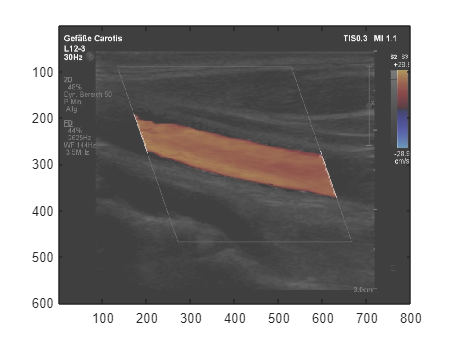

figure()
imagesc(us_1_b1)
hold on
imagesc(us_1_d1)
hold off
alpha(0.5)

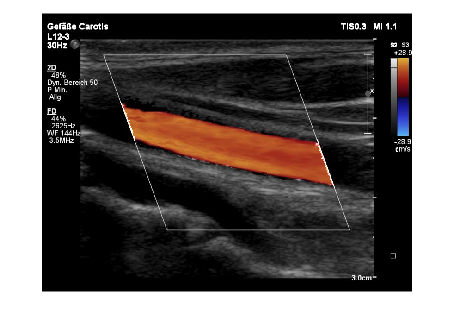

ueberlagerung_bild = imadd(us_1_b1, us_1_d1);
imshow(ueberlagerung_bild)

Medizinische Bilddaten von CT und MRT werden üblicherweise im DICOM Format gespeichert. Wählen Sie ein Bild aus dem mitgegebenen DICOM Datensatz aus, lesen Sie die Metadaten aus und stellen Sie das Bild dar. 

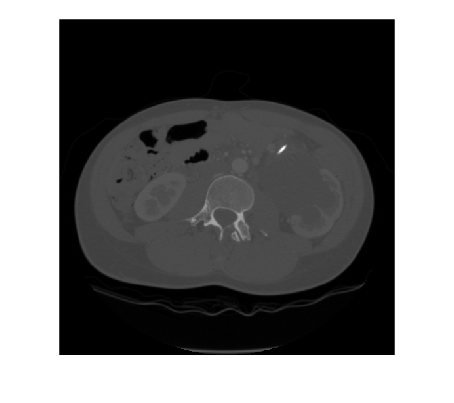

%Ihre Lösung
ct_mrt_info = dicominfo("./series-000001/series-000001/image-000228.dcm");
ct_mrt_reader = dicomread(ct_mrt_info);
imshow(ct_mrt_reader, [])